# MATLAB for Geoscientists 1 - University of Maryland

## Making sure your MATLAB is up to date

You can download the latest version of MATLAB for free at [terpware.umd.edu.](http://terpware.umd.edu) Follow the instructions to login with your University of Maryland email address and password, which will bring you to UMD's portal for downloading the latest versions of MATLAB. 

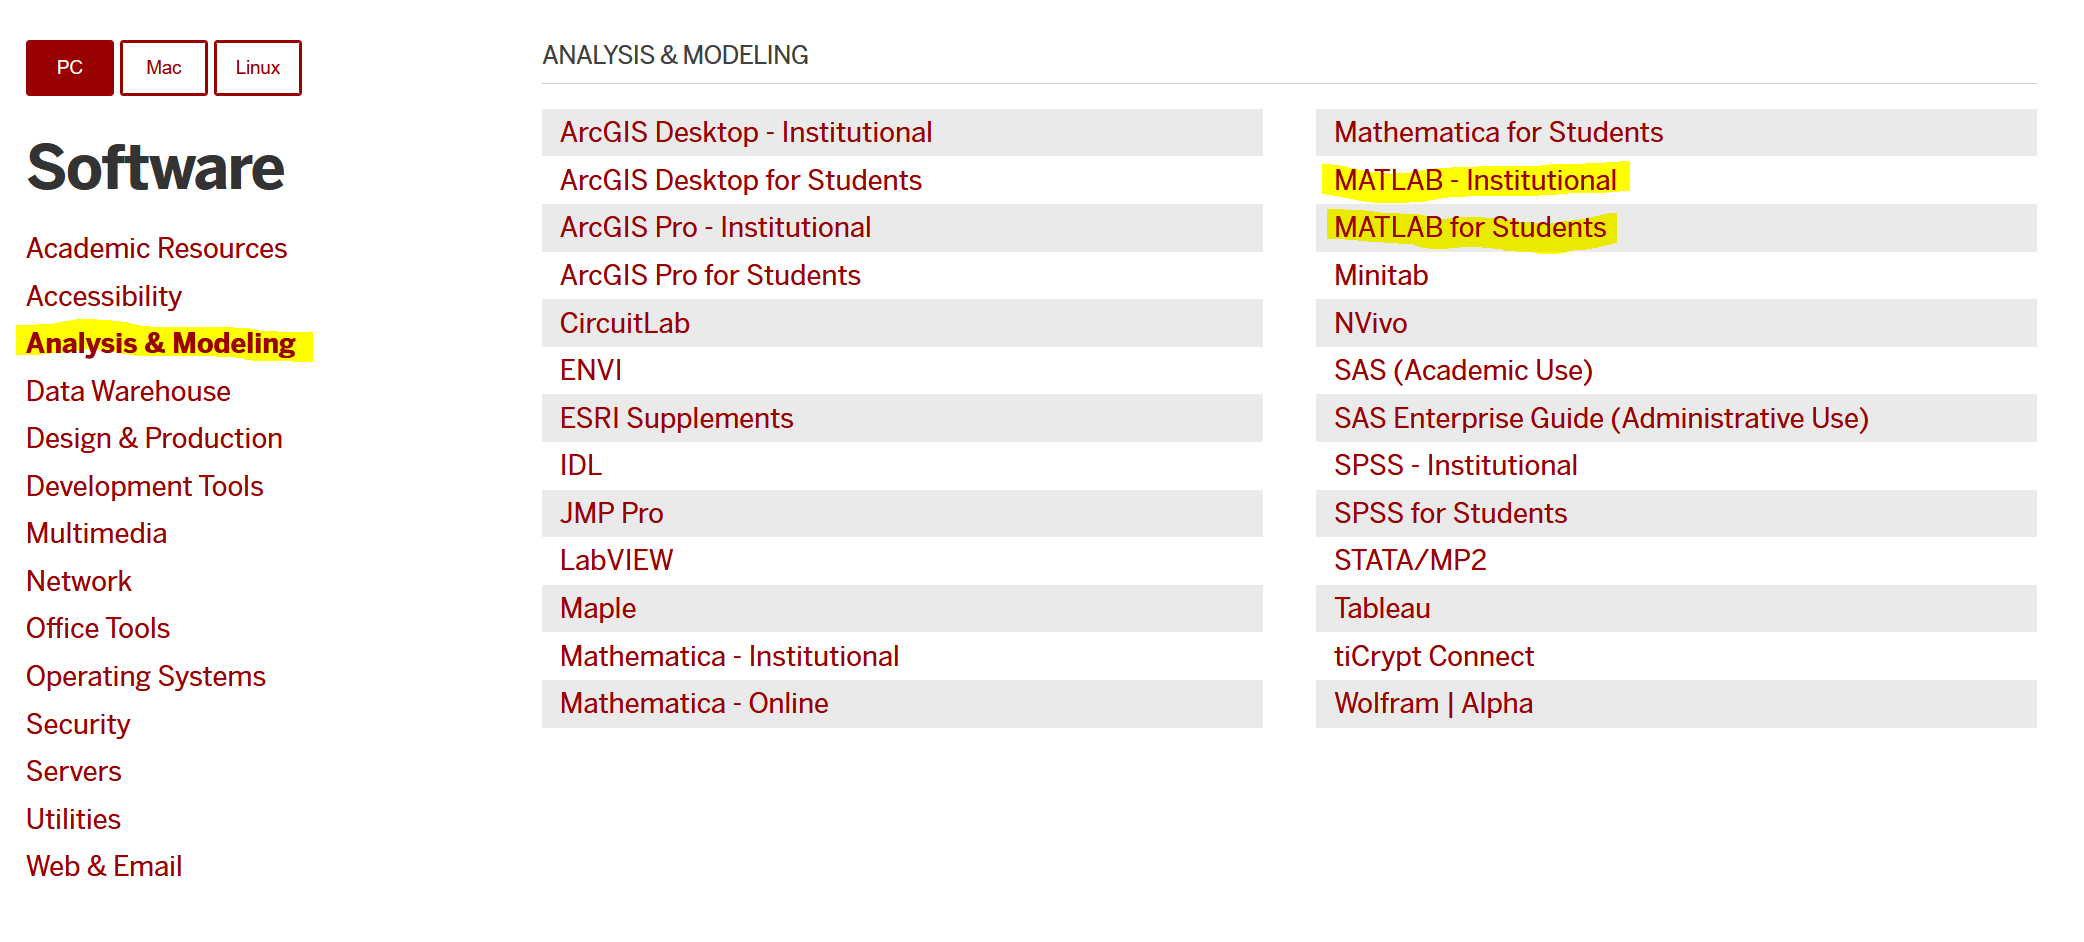

If you are updating your MATLAB to the latest release, the software will simply install the same way as if you were downloading it for the first time. MATLAB has unique installs for each version, so you can have multiple versions (e.g., 2016a, 2021b, 2022a) installed on the same machine without overwriting each other. 

MATLAB is backwards compatible with older versions. Sometimes, however, certain functionalities will be updated. If you are using more recent versions of MATLAB, the program will identify for you if a functionality your code uses has been changed via its built in Code Analyzer. [MATLAB Release Notes](https://www.mathworks.com/help/matlab/release-notes.html) documents all updates and lets you compare different MATLAB releases to see what's changed.

# Data Retrieval and Import

This section illustrates automated import of a data table from a .xlsx file. **For an example of how to automate data download from a specific website, please refer to **[**this example script.**](matlab:open('/DataRetrievalExample.mlx'))

### Load the andesite rock sample data

This data has been downloaded as a .xlsx file from Earthchem.org.

filename = 'earthchem_download_15510';
andesites = importAndesitefile1(filename);

# Plot Rock Sample Data

Let's make a scatter plot to visually identify potentially anomalous measurements.

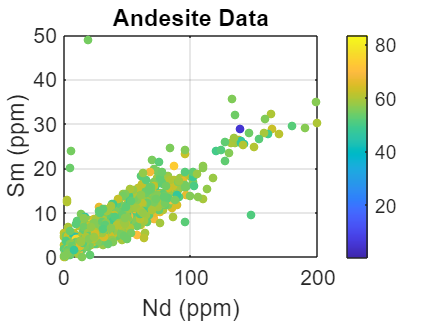

figure
createAndesitefig(andesites.ND,andesites.SM,[],andesites.SIO2)

# Logical Indexing of Data

m = rand(1,9)

m =     0.3922    0.6555    0.1712    0.7060    0.0318    0.2769    0.0462    0.0971    0.8235


idx = m>.7

idx = 1×9 logical array
   0   0   0   1   0   0   0   0   1


m(idx)

ans =     0.7060    0.8235


m(m>.7)

ans =     0.7060    0.8235


### Filter Data to Exclude Outlier Nd and Sm

filt_idx = andesites.ND<200 & andesites.SM<40;

filteredNd = andesites.ND(filt_idx);
filteredSm = andesites.SM(filt_idx);
filteredSiO2 = andesites.SIO2(filt_idx);

### Plot Filtered Data

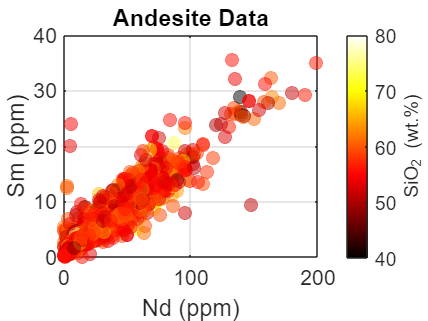

figure
createAndesitefig(filteredNd,filteredSm,100,filteredSiO2)

% You can also always change the properties of a figure via code, e.g.:
colormap(hot)
alpha(0.5)
cb = colorbar;

ylabel(cb,'SiO_2 (wt.%)')
caxis([40 80])

# Curve Fitting

Launch curve fitter app by clicking on it in the Apps tab.

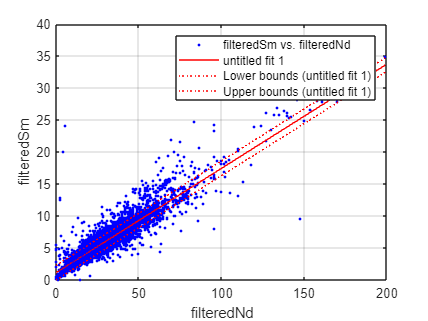

ans =      Linear model Poly1:
     ans(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.1634  (0.1627, 0.164)
       p2 =       1.067  (1.05, 1.083)

createNdSmFit(filteredNd, filteredSm)

# Display Sample Locations on Globe

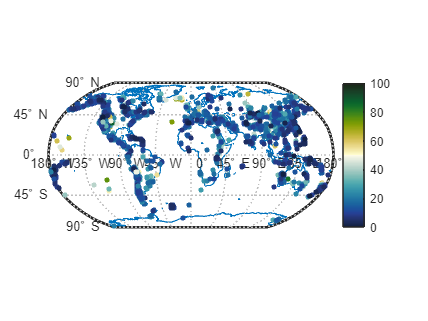

load coastlines

figure
axesm('apianus')
worldmap('world')

hold on
plotm(coastlat,coastlon,'linewidth',1)
scatterm(andesites.LATITUDE,andesites.LONGITUDE,15,andesites.ND,'filled')


colorbar
colormap(cmocean('delta')) % see the FileExchange resources at the end of this 
% document for a list of community-created colormaps and functions. You
% must download the 'cmocean' function in order for this colormap to
% display. Otherwise, choose a different, built-in colormap, like 'parula'.

clim([0 100]) 

# Toolboxes and FileExchange

### [File Exchange > Sciences > Earth, Ocean, Atmospheric Sciences](https://www.mathworks.com/matlabcentral/fileexchange?category%5B%5D=support%2Fearth-oce840&q=)

There are thousands of publicly available files, functions, and toolboxes on the MATLAB File Exchange and on GitHub. The link above brings you to a list of files made specifically for the EOAS community, but there are many, many, MANY other useful tools available. 

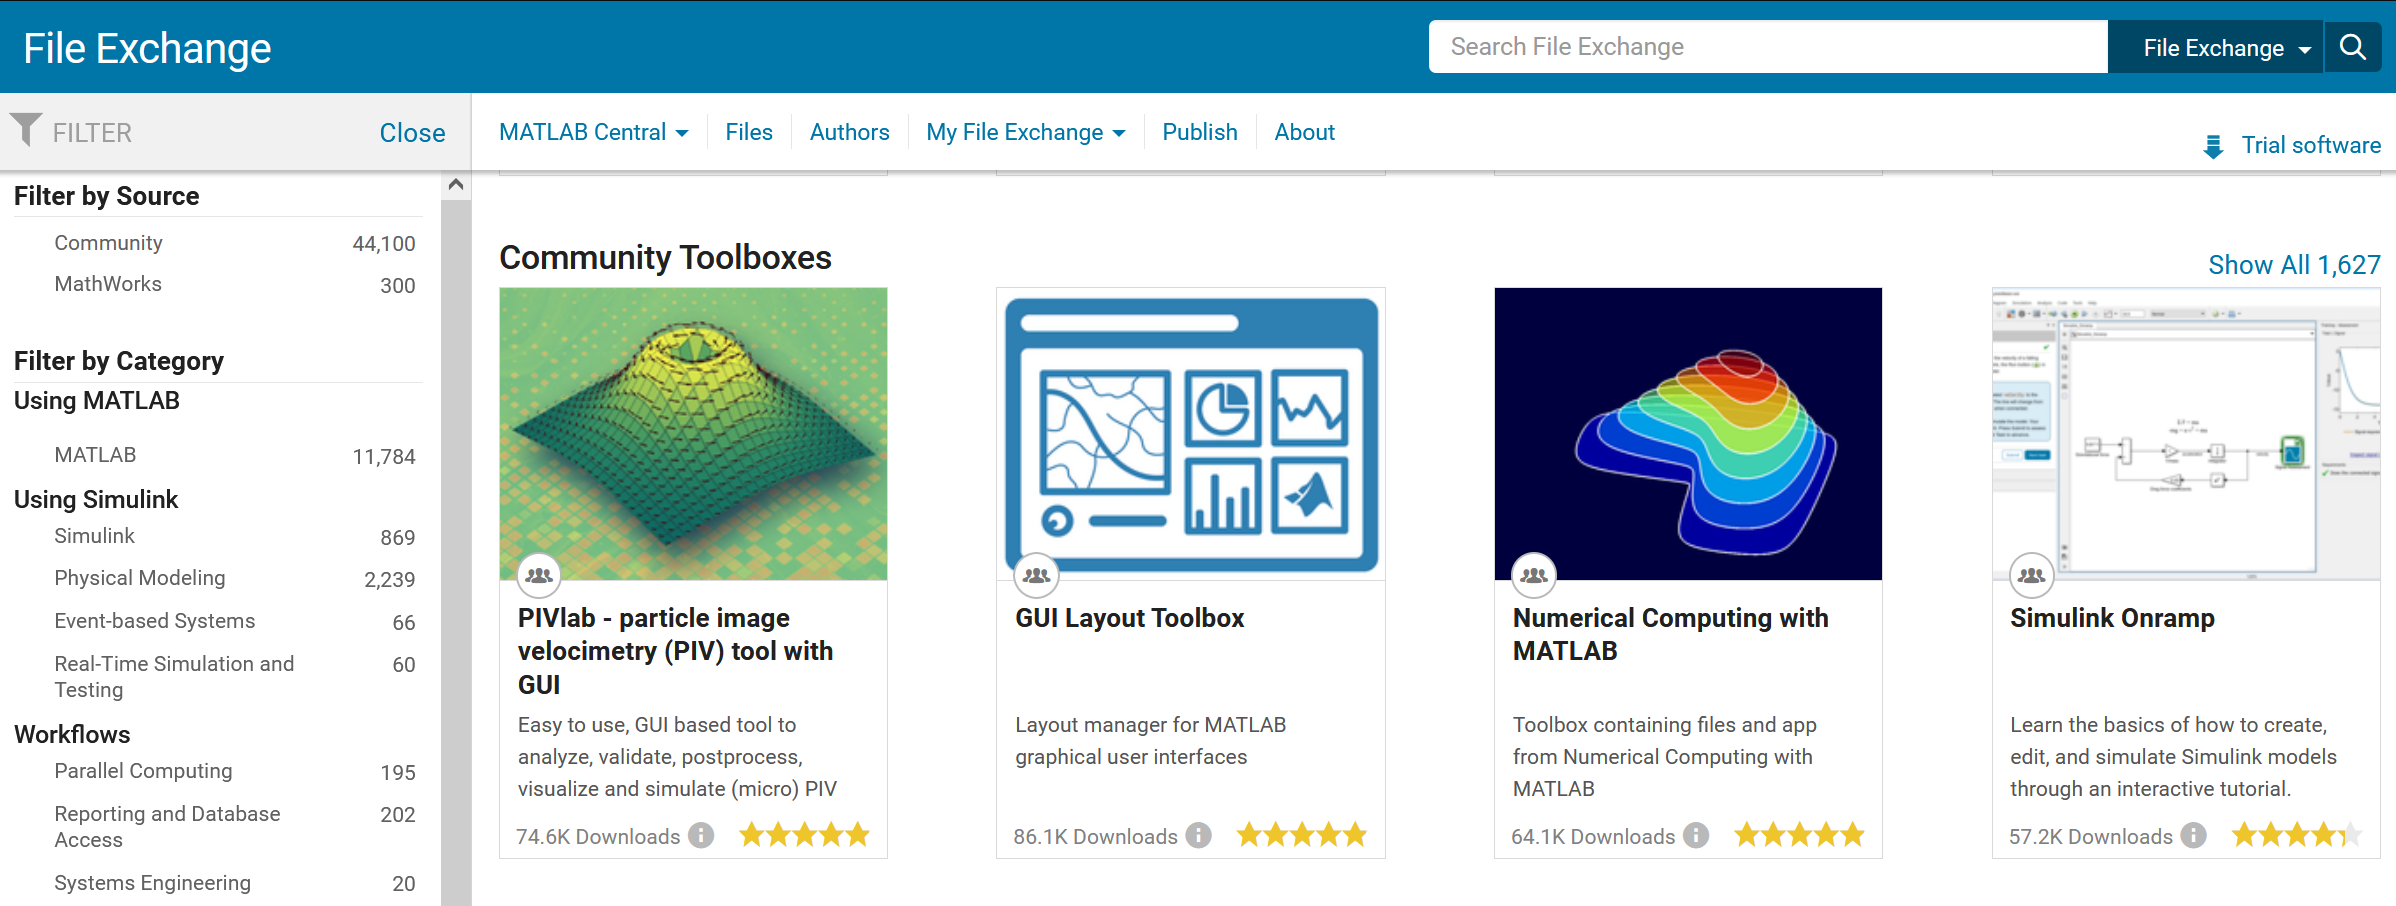

#### File Exchange functions used in this document's examples:

- [borders](https://www.mathworks.com/matlabcentral/fileexchange/50390-borders)

- [cm_ocean perceptually-uniform colormaps](https://www.mathworks.com/matlabcentral/fileexchange/57773-cmocean-perceptually-uniform-colormaps?s_tid=srchtitle)

- [MatPlotLib Perceptually Uniform Colormaps](https://www.mathworks.com/matlabcentral/fileexchange/62729-matplotlib-perceptually-uniform-colormaps?s_tid=srchtitle)

[](https://www.mathworks.com/matlabcentral/fileexchange/50390-borders)